# Documentation: Box model of the carbon cycle and zero-dimensional model fo the climate

The seven-box model of the carbon cycle and a zero-dimensional model of the climate are combined hereinafter. The carbon cycle model defines seven boxes representing different components of the Earth system, including the atmosphere, surface ocean, intermediate ocean, deep ocean, sediment, biosphere, and soil. The model simulates the exchange of carbon among these boxes over time, using historical data and predictions for future emissions from fossil fuel combustion and land-use changes.

The code reads in historical data on carbon emissions from fossil fuels and land-use changes, as well as predictions for these emissions based on different scenarios. The mclimate model incorporates the carbon cycle model and solar irradiance data and calculates the change in global temperature over time based on a feedback system. 

clearvars;close all;clc;
set(0, 'DefaultFigureRenderer', 'painters');
% box 1 = atmosphere
% box 2 = surface ocean
% box 3 = intermediate ocean
% box 4 = deep ocean
% box 5 = sediment
% box 6 = biosphere
% box 7 = soil
Nbox = 7;

% Define time step and simulation duration
dt = 1/12; % Time step (unit:yr)
tmax = 300; % Simulation duration (yr)
t = 1750 + [0:dt:350];
N = numel(t);

## Load emissions data (historical)

% Emissions from Fossile fual and industry
clf;close all
load('gamma_ourWorldInData.mat','Year','Total')
Total_fossileFuel = Total*3/11*1e6/1e15;

% Emissions from land use change
load('delta_ourWorldInData.mat','year','Land_use_change')
Land_use_change = Land_use_change*3/11*1e6/1e15;


## Load emissions data (predictions)

Data are interpolated onto a  new time array

Tab = readtable('ipcc-scenarios.csv');


scenario = {'SSP1 - Baseline','SSP2 - Baseline','SSP3 - Baseline','SSP4 - Baseline','SSP5 - Baseline'};

gamma = zeros(numel(scenario),numel(t));
delta = zeros(numel(scenario),numel(t));
for pp= 1:numel(scenario),
    indS = find(contains(Tab{:,1},scenario(pp)));
    CO2_prediction_fossil = Tab.FossilCO2Emissions(indS)*3/11*1e6/1e15;
    CO2_prediction_land = Tab.LandCO2Emissions(indS)*3/11*1e6/1e15;
    t_prediction = Tab.Year(indS);


    [tp,ind,IB] = unique([Year(~isnan(Year))',t_prediction']);
    C = [Total_fossileFuel(~isnan(Year))',CO2_prediction_fossil'];
    C = C(ind);
    gamma(pp,:) = interp1(tp,C,t,'pchip');


    [tp,ind,IB] = unique([year(~isnan(year))',t_prediction']);
    C = [Land_use_change(~isnan(year))',CO2_prediction_land'];
    C = C(ind);
    delta(pp,:) = interp1(tp,C,t,'pchip');
    indMin = find(t<min(tp));
    delta(pp,indMin) = C(1); % extrpolation for earliest time
end

## Visualize emissions (historical and predicted)

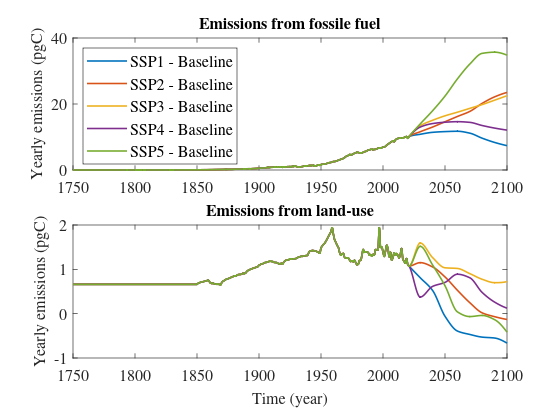

clf;close all;
figure
tiledlayout(2,1,"TileSpacing","tight")
nexttile
plot(t,gamma,'linewidth',1.2);
% xlabel('Time (year)')
ylabel('Yearly emissions (pgC)')
set(gcf,'color','w')
title('Emissions from fossile fuel')
legend(scenario{:},'location','northwest')

nexttile
plot(t,delta,'linewidth',1.2);
xlabel('Time (year)')
ylabel('Yearly emissions (pgC)')
set(gcf,'color','w')
title('Emissions from land-use')

set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

## Get solar irradiance data 

Source: [https://lasp.colorado.edu/lisird/data/nrl2_tsi_P1Y](https://lasp.colorado.edu/lisird/data/nrl2_tsi_P1Y) 

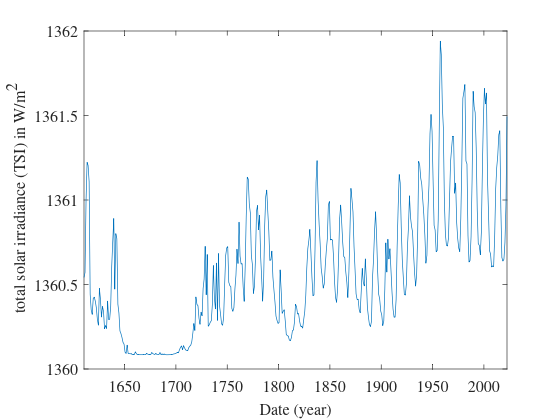

tsi = double(ncread('tsi_v02r01_yearly_s1610_e2022_c20230120.nc','TSI'));
time = days(ncread("tsi_v02r01_yearly_s1610_e2022_c20230120.nc",'time')) + datetime(1610,1,1);

figure
plot(time,tsi)
xlabel('Date (year)')
ylabel(' total solar irradiance (TSI) in W/m^2')
set(gcf,'color','w')

set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

## Change in global temperatures

Code inspired by [https://computationalthinking.mit.edu/Fall20/lecture20/](https://computationalthinking.mit.edu/Fall20/lecture20/) 

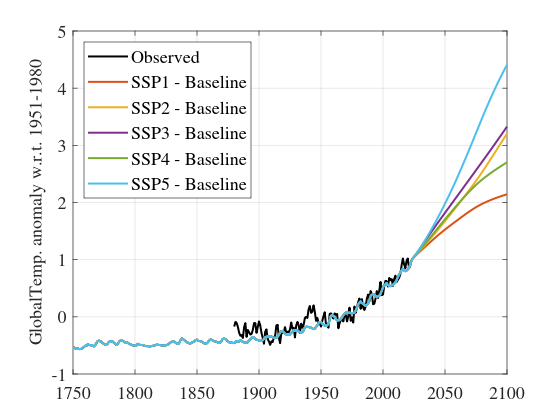

clear Year year
t1 = years(t) + datetime(0,1,1,15,0,0);

% Interpolate solar irradiance onto new vector
S = interp1(time,tsi,t1,'nearest','extrap');% in W m^-2  --- Solar irradiance at the top of the atmosphere

T0 = 15; %  Steady state preindustrial Global average temperature
alpha = 0.31; % albedo
B = -1.3; % climate feedback in W m^-2 K^-1, negative for stabilization effect
C = 51; % atmosphere and upper-ocean heat capacity  in J m^-2 K^-1
a = 3.7./log(2) ; % c in W m^-2
A = S(1).*(1-alpha)/4 + B.*T0; % Initial value
T = zeros(numel(scenario),N);
T(:,1)=T0; % Initialisation

for pp= 1:numel(scenario),
    [C_CO2] = run7Box(t,gamma(pp,:),delta(pp,:));
    for ii=1:N-1

        % Q = Incoming solar radiation - outgoing thermal radiation
        Q = S(ii).*(1-alpha)/4 - A + B.*T(pp,ii); 

        % Ration of atmospheric concentration of CO2  normalized by
        % preindustrial value
        x = C_CO2(1,ii)./C_CO2(1);
        
        % Global temperature  from Earth's planetary energy balance
        T(pp,ii+1) = (Q + a.*log(x)).*dt + T(pp,ii) ;
    end

end
clf;close all;
load('T_anomaly_1850.mat','t_obs','T_obs') % Load temperature anomaly (from NASA)
[~,indStart]=min(abs(t-1951));
[~,indEnd]=min(abs(t-1980));


figure
plot(t_obs,T_obs,'linewidth',1.5,'color','k');
hold on
plot(t,T-mean(T(:,indStart:indEnd),2),'linewidth',1.5);
grid on
ylabel('GlobalTemp. anomaly w.r.t. 1951-1980')
legend('Observed',scenario{:},'location','northwest')
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')